# Dimensionality Reduction by SA-LSUN

## Preparation

clc, clear
close all

## Loading Input Signal

Datasetfolder ='./Experience1/Dataset';
files = dir(fullfile(Datasetfolder,'*.mat'));
data = load(fullfile(Datasetfolder,files(1).name));
u = single(data.u);

if canUseGPU
    disp("Use GPU")
    u = gpuArray(u);
end

Use GPU


[szy,szx,szt] = size(u);

## Setting

Setting of LSUN

blksz = [4, 4];             % Block Size
p = prod(blksz);            % Number of Channel
nCoefs = 2;                 % Number of Coefficient
ovlp = [3,3];               % Number of Overlap(Fixed)
neibor = [3,3];             % Number of input blocks for the parameter estimator
nBlks = [szy,szx]./blksz;   % Number of Block
N = prod(nBlks);            % All Blocks

% Mask
coefMask = reshape([ones(nCoefs,1); zeros(p-nCoefs,1)],2,[]).';
coefMask = coefMask(:);

Setting of Parameter Estimator

He = @(x,y) sqrt(2/y)*randn(x,y);

h_i = 2;        % width of parameter estimator(initial rotation)
h_m = 2;        % width of parameter estimator(intermediate rotation)
part = 3;       % number of residual blocks

w_ini = cell(2*part+1,1);          b_ini = cell(2*part+1,1);          g_ini = cell(part,1);          beta_ini = cell(part,1);
w_hor = cell(2*part+1,ovlp(2)-1);  b_hor = cell(2*part+1,ovlp(2)-1);  g_hor = cell(part,ovlp(2)-1);  beta_hor = cell(part,ovlp(2)-1);
w_ver = cell(2*part+1,ovlp(1)-1);  b_ver = cell(2*part+1,ovlp(1)-1);  g_ver = cell(part,ovlp(1)-1);  beta_ver = cell(part,ovlp(1)-1);

## Learnable Parameter of NN

% Initial Rotation Parameter
for i = 1:part
    g_ini{i} = ones((p-1)*prod(neibor),1);                          beta_ini{i} = zeros((p-1)*prod(neibor),1);
    w_ini{2*i-1} = He(h_i*(p-1)*prod(neibor),(p-1)*prod(neibor));     b_ini{2*i-1} = zeros(h_i*(p-1)*prod(neibor),1);
    w_ini{2*i} = zeros((p-1)*prod(neibor),h_i*(p-1)*prod(neibor));       b_ini{2*i} = zeros((p-1)*prod(neibor),1);
end
w_ini{end} = zeros(p*(p-2)/4-(p/2-1),(p-1)*prod(neibor));      b_ini{end} = zeros(p*(p-2)/4-(p/2-1),1);

% Horizontal Direction Rotation Parameter
for j = 1:ovlp(2)-1
    for i = 1:part
        g_hor{i,j} = ones(p/2*prod(neibor),1);                      beta_hor{i,j} = zeros(p/2*prod(neibor),1);
        w_hor{2*i-1,j} = He(h_m*p/2*prod(neibor),p/2*prod(neibor));   b_hor{2*i-1,j} = zeros(h_m*p/2*prod(neibor),1);
        w_hor{2*i,j} = zeros(p/2*prod(neibor),h_m*p/2*prod(neibor));     b_hor{2*i,j} = zeros(p/2*prod(neibor),1);
    end
    w_hor{end,j} = zeros(p*(p-2)/8,p/2*prod(neibor));          b_hor{end,j} = zeros(p*(p-2)/8,1);
end

% Vertial Direction Rotation Parameter
for j = 1:ovlp(1)-1
    for i = 1:part
        g_ver{i,j} = ones(p/2*prod(neibor),1);                      beta_ver{i,j} = zeros(p/2*prod(neibor),1);
        w_ver{2*i-1,j} = He(h_m*p/2*prod(neibor),p/2*prod(neibor));   b_ver{2*i-1,j} = zeros(h_m*p/2*prod(neibor),1);
        w_ver{2*i,j} = zeros(p/2*prod(neibor),h_m*p/2*prod(neibor));     b_ver{2*i,j} = zeros(p/2*prod(neibor),1);
    end
    w_ver{end,j} = zeros(p*(p-2)/8,p/2*prod(neibor));          b_ver{end,j} = zeros(p*(p-2)/8,1);
end

if canUseGPU
    w_ini = cellfun(@(x) gpuArray(single(x)),w_ini,'UniformOutput', false);  b_ini = cellfun(@(x) gpuArray(single(x)),b_ini,'UniformOutput', false);
    g_ini = cellfun(@(x) gpuArray(single(x)),g_ini,'UniformOutput', false);  beta_ini = cellfun(@(x) gpuArray(single(x)),beta_ini,'UniformOutput', false);
    w_hor = cellfun(@(x) gpuArray(single(x)),w_hor,'UniformOutput', false);  b_hor = cellfun(@(x) gpuArray(single(x)),b_hor,'UniformOutput', false);
    g_hor = cellfun(@(x) gpuArray(single(x)),g_hor,'UniformOutput', false);  beta_hor = cellfun(@(x) gpuArray(single(x)),beta_hor,'UniformOutput', false);
    w_ver = cellfun(@(x) gpuArray(single(x)),w_ver,'UniformOutput', false);  b_ver = cellfun(@(x) gpuArray(single(x)),b_ver,'UniformOutput', false);
    g_ver = cellfun(@(x) gpuArray(single(x)),g_ver,'UniformOutput', false);  beta_ver = cellfun(@(x) gpuArray(single(x)),beta_ver,'UniformOutput', false);
end

gradsH = cell(8,ovlp(2)-1);
gradsV = cell(8,ovlp(1)-1);

## Application of 2-D LSUN

Training Setting

% epochs
maxEpochs = 100;

% initial rotation
AG_w_in = cell(2*part+1,1);     AG_b_in = cell(2*part+1,1);
AG_g_in = cell(part,1);         AG_beta_in = cell(part,1);
ASG_w_in = cell(2*part+1,1);    ASG_b_in = cell(2*part+1,1);
ASG_g_in = cell(part,1);        ASG_beta_in = cell(part,1);

% intermediate rotation
% horizontal
AG_w_hor = cell(2*part+1,ovlp(2)-1);        AG_b_hor = cell(2*part+1,ovlp(2)-1);
AG_g_hor = cell(part,ovlp(2)-1);            AG_beta_hor = cell(part,ovlp(2)-1);
ASG_w_hor = cell(2*part+1,ovlp(2)-1);       ASG_b_hor = cell(2*part+1,ovlp(2)-1);
ASG_g_hor = cell(part,ovlp(2)-1);           ASG_beta_hor = cell(part,ovlp(2)-1);
% vertical
AG_w_ver = cell(2*part+1,ovlp(1)-1);        AG_b_ver = cell(2*part+1,ovlp(1)-1);
AG_g_ver = cell(part,ovlp(1)-1);            AG_beta_ver = cell(part,ovlp(1)-1);
ASG_w_ver = cell(2*part+1,ovlp(1)-1);       ASG_b_ver = cell(2*part+1,ovlp(1)-1);
ASG_g_ver = cell(part,ovlp(1)-1);           ASG_beta_ver = cell(part,ovlp(1)-1);

% hyperparameter in adam
B1 =0.9;
B2 = 0.999;
ep = 1e-12;

% learnrate(cosine decay)
initialLearnRate = 1e-3;
finalLearnRate = 1e-5;

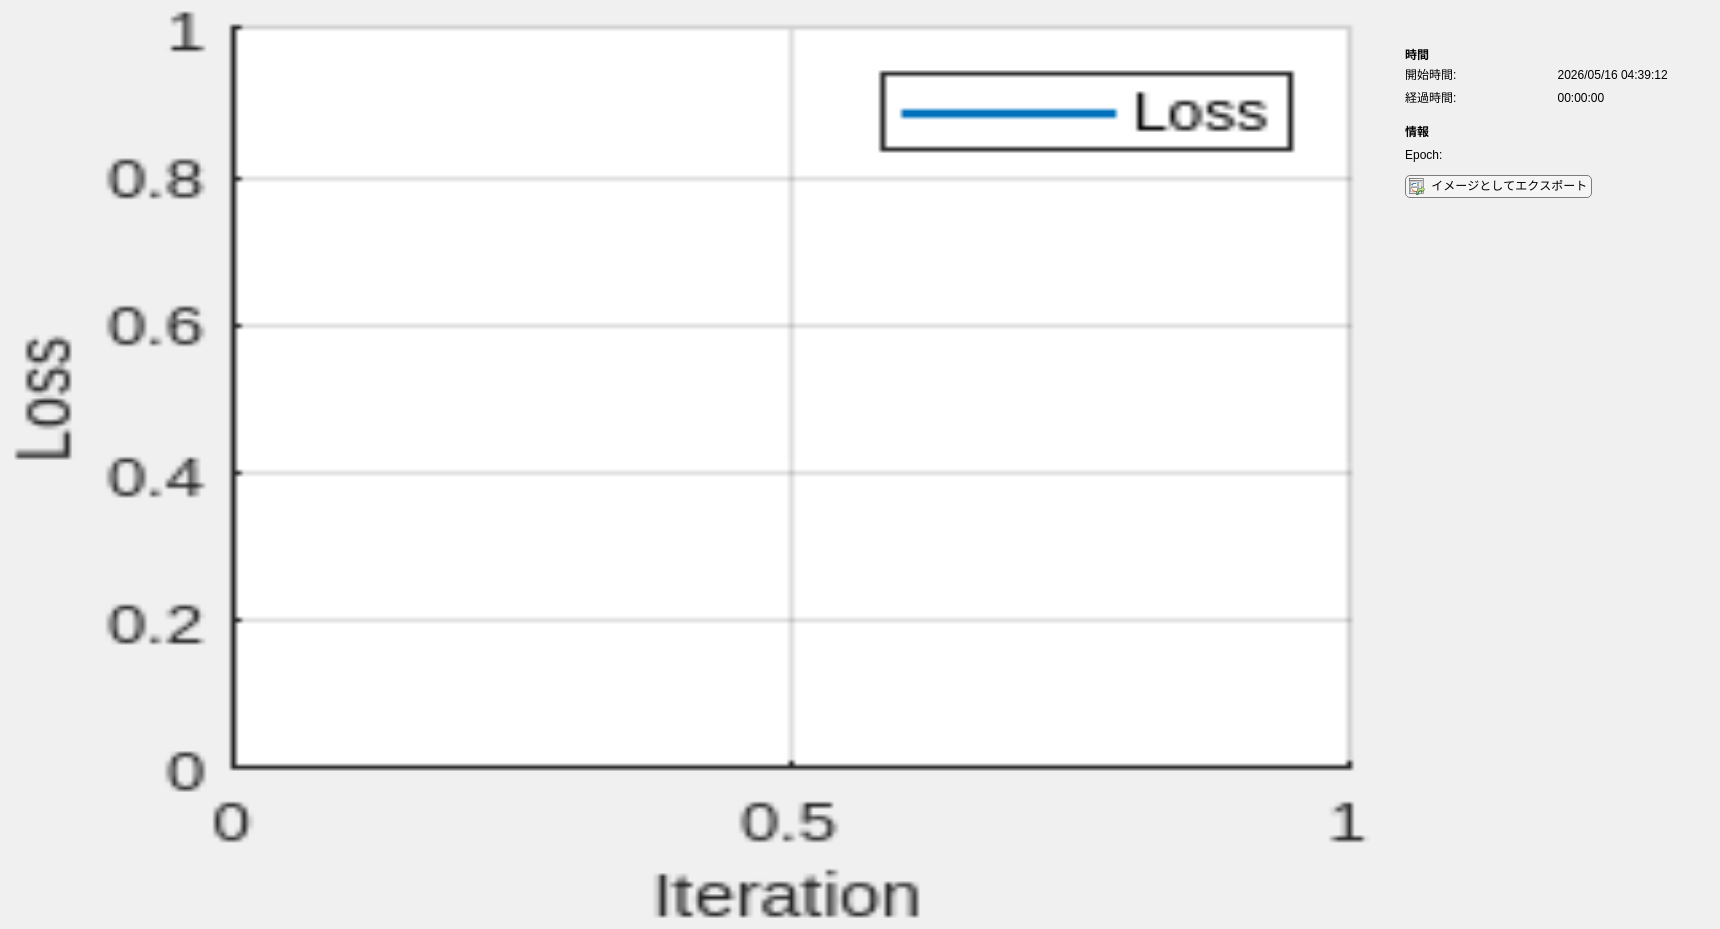

% plot training progress
monitor = trainingProgressMonitor(Metrics="Loss",Info="Epoch",XLabel="Iteration");

### **forward**

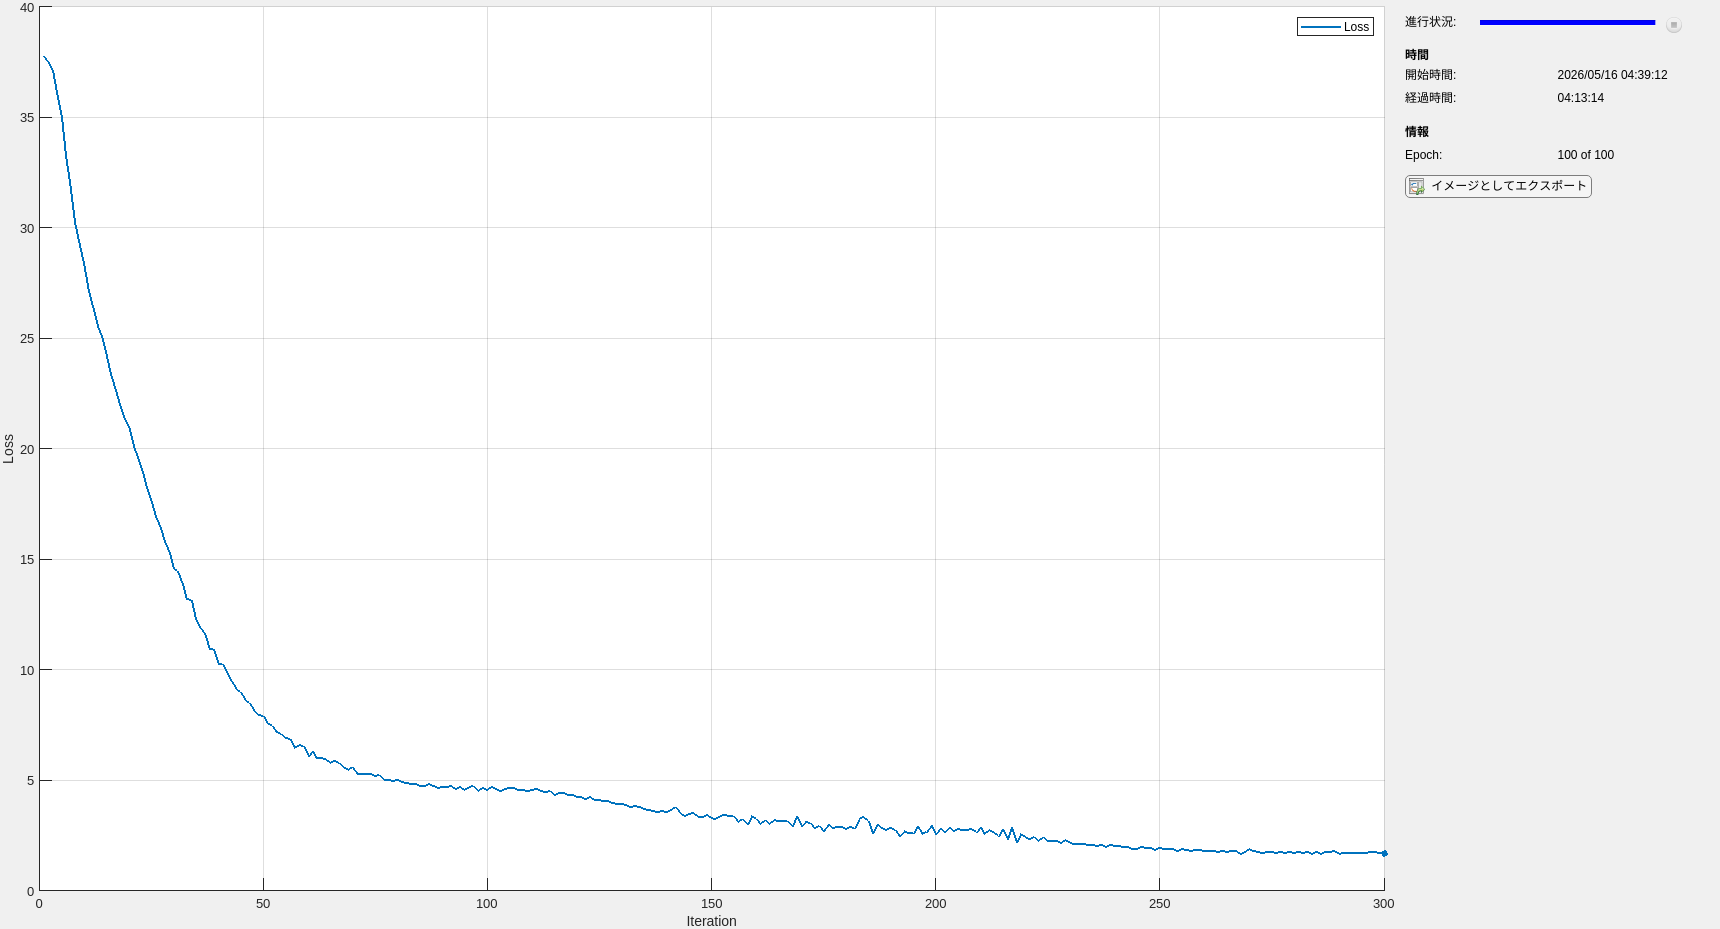

mbsize = 64;        % minibatch size
nofData = szt;
numIterationsPerEpoch = floor(nofData / mbsize);
numIterations = maxEpochs * numIterationsPerEpoch;
loss = zeros(numIterations,1);

epoch = 0;
iteration = 0;

% training parameter estimator
for nofEpoch = 1:maxEpochs
epoch = epoch + 1;
idx = randperm(szt);

    for iBatch = 1:mbsize:(nofData-mbsize+1)
    iteration = iteration + 1;

    batch_idx = idx(iBatch:iBatch+mbsize-1);
    u_batch = u(:,:,batch_idx);

    nBatchs = size(u_batch,3);

    % DCT
    X_DCT = DCT_2D(u_batch, blksz(1), blksz(2));

    % initial rotation
    angles0 = lsunAngleEstimate(X_DCT,w_ini,b_ini, ...
        g_ini,beta_ini,neibor,"Initial");
    
    X_R0 = Rot_initial(X_DCT,angles0);
    
    % right shift + butterfly + rotation
    X_shift_R = atomext_(X_R0,'Right','Difference');
    
    anglesUh1 = lsunAngleEstimate(X_shift_R, w_hor(:,1),b_hor(:,1), ...
        g_hor(:,1),beta_hor(:,1),neibor,"Inter");
    
    X_R1 = Rot_inter(X_shift_R,anglesUh1,-1);
    
    % left shift + butterfly + rotation
    X_shift_L = atomext_(X_R1,'Left','Sum');
    
    anglesUh2 = lsunAngleEstimate(X_shift_L, w_hor(:,2),b_hor(:,2), ...
        g_hor(:,2),beta_hor(:,2),neibor,"Inter");
    
    X_R2 = Rot_inter(X_shift_L,anglesUh2,1);
    
    % down shift + butterfly + rotation
    X_shift_D = atomext_(X_R2,'Down','Difference');
    
    anglesUv1 = lsunAngleEstimate(X_shift_D, w_ver(:,1),b_ver(:,1), ...
        g_ver(:,1),beta_ver(:,1),neibor,"Inter");
    
    X_R3 = Rot_inter(X_shift_D,anglesUv1,-1);
    
    % up shift + butterfly + rotation
    X_shift_U = atomext_(X_R3,'Up','Sum');
    
    anglesUv2 = lsunAngleEstimate(X_shift_U, w_ver(:,2),b_ver(:,2), ...
        g_ver(:,2),beta_ver(:,2),neibor,"Inter");
    
    dlX = Rot_inter(X_shift_U,anglesUv2,1);
    
    % mask
    dlX = coefMask(:).*dlX;
    
    % loss function
    n_loss = sum(u_batch.^2,"all")/nBatchs- sum(dlX.^2,"all")/nBatchs;
    
    % Backward
    dLdX = -2.*dlX;
    [dLdX, dLdW4] = backward_Un(X_shift_U, dLdX, anglesUv2,1);
    gradsV(:,2) = backward_Estimator(X_shift_U,dLdW4,w_ver(:,2),b_ver(:,2),g_ver(:,2),beta_ver(:,2),neibor,"Inter");
    dLdX = backward_shift(dLdX,'Up','Sum');
    
    [dLdX, dLdW3] = backward_Un(X_shift_D, dLdX, anglesUv1,-1);
    gradsV(:,1) = backward_Estimator(X_shift_D,dLdW3,w_ver(:,1),b_ver(:,1),g_ver(:,1),beta_ver(:,1),neibor,"Inter");
    dLdX = backward_shift(dLdX,'Down','Difference');
    
    [dLdX, dLdW2] = backward_Un(X_shift_L, dLdX, anglesUh2,1);
    gradsH(:,2) = backward_Estimator(X_shift_L,dLdW2,w_hor(:,2),b_hor(:,2),g_hor(:,2),beta_hor(:,2),neibor,"Inter");
    dLdX = backward_shift(dLdX,'Left','Sum');
    
    [dLdX, dLdW1] = backward_Un(X_shift_R, dLdX, anglesUh1,-1);
    gradsH(:,1) = backward_Estimator(X_shift_R,dLdW1,w_hor(:,1),b_hor(:,1),g_hor(:,1),beta_hor(:,1),neibor,"Inter");
    dLdX = backward_shift(dLdX,'Right','Difference');
    
    [dLdX, dLdW0] = backward_U0W0(X_DCT, dLdX, angles0);
    grads0 = backward_Estimator(X_DCT,dLdW0,w_ini,b_ini,g_ini,beta_ini,neibor,"Initial");
    dLdX = backward_DCT(dLdX, blksz(1), blksz(2));
    
    learnRate = finalLearnRate +(initialLearnRate - finalLearnRate) * (1 + cos(pi * iteration/maxEpochs))/2;

    % update learnable parameter
    for i = 1:part
        dw1= grads0{1}; db1 = grads0{2}; dw2 = grads0{3}; db2 = grads0{4}; dg = grads0{5}; dbeta = grads0{6};
        
        [g_ini{i},AG_g_in{i},ASG_g_in{i}] = adamupdate(g_ini{i}, dg(:,:,i),AG_g_in{i},ASG_g_in{i},iteration,learnRate,B1,B2,ep);
        [beta_ini{i},AG_beta_in{i},ASG_beta_in{i}] = adamupdate(beta_ini{i}, dbeta(:,:,i),AG_beta_in{i},ASG_beta_in{i},iteration,learnRate,B1,B2,ep);
        
        [w_ini{2*i-1},AG_w_in{2*i-1},ASG_w_in{2*i-1}] = adamupdate(w_ini{2*i-1},dw1(:,:,i),AG_w_in{2*i-1},ASG_w_in{2*i-1},iteration,learnRate,B1,B2,ep);
        [b_ini{2*i-1},AG_b_in{2*i-1},ASG_b_in{2*i-1}] = adamupdate(b_ini{2*i-1},db1(:,:,i),AG_b_in{2*i-1},ASG_b_in{2*i-1},iteration,learnRate,B1,B2,ep);
        [w_ini{2*i},AG_w_in{2*i},ASG_w_in{2*i}] = adamupdate(w_ini{2*i},dw2(:,:,i),AG_w_in{2*i},ASG_w_in{2*i},iteration,learnRate,B1,B2,ep);
        [b_ini{2*i},AG_b_in{2*i},ASG_b_in{2*i}] = adamupdate(b_ini{2*i},db2(:,:,i),AG_b_in{2*i},ASG_b_in{2*i},iteration,learnRate,B1,B2,ep);
    end
    [w_ini{end},AG_w_in{end},ASG_w_in{end}] = adamupdate(w_ini{end}, grads0{end-1},AG_w_in{end},ASG_w_in{end},iteration,learnRate,B1,B2,ep);
    [b_ini{end},AG_b_in{end},ASG_b_in{end}] = adamupdate(b_ini{end}, grads0{end},AG_b_in{end},ASG_b_in{end},iteration,learnRate,B1,B2,ep);
    
    for j = 1:ovlp(2)-1
        for i = 1:part
            dw1= gradsH{1,j}; db1= gradsH{2,j}; dw2= gradsH{3,j}; db2= gradsH{4,j}; dg = gradsH{5,j}; dbeta = gradsH{6,j};
            
            [g_hor{i,j},AG_g_hor{i,j},ASG_g_hor{i,j}] = adamupdate(g_hor{i,j}, dg(:,:,i), AG_g_hor{i,j},ASG_g_hor{i,j},iteration,learnRate,B1,B2,ep);
            [beta_hor{i,j},AG_beta_hor{i,j},ASG_beta_hor{i,j}] = adamupdate(beta_hor{i,j}, dbeta(:,:,i), AG_beta_hor{i,j},ASG_beta_hor{i,j},iteration,learnRate,B1,B2,ep);
            
            [w_hor{2*i-1,j},AG_w_hor{2*i-1,j},ASG_w_hor{2*i-1,j}] = adamupdate(w_hor{2*i-1,j},dw1(:,:,i),AG_w_hor{2*i-1,j},ASG_w_hor{2*i-1,j},iteration,learnRate,B1,B2,ep);
            [b_hor{2*i-1,j},AG_b_hor{2*i-1,j},ASG_b_hor{2*i-1,j}] = adamupdate(b_hor{2*i-1,j},db1(:,:,i),AG_b_hor{2*i-1,j},ASG_b_hor{2*i-1,j},iteration,learnRate,B1,B2,ep);
            [w_hor{2*i,j},AG_w_hor{2*i,j},ASG_w_hor{2*i,j}] = adamupdate(w_hor{2*i,j}, dw2(:,:,i), AG_w_hor{2*i,j}, ASG_w_hor{2*i,j},iteration,learnRate,B1,B2,ep);
            [b_hor{2*i,j},AG_b_hor{2*i,j},ASG_b_hor{2*i,j}] = adamupdate(b_hor{2*i,j}, db2(:,:,i), AG_b_hor{2*i,j},ASG_b_hor{2*i,j},iteration,learnRate,B1,B2,ep);
        end
        [w_hor{end,j},AG_w_hor{end,j},ASG_w_hor{end,j}] = adamupdate(w_hor{end,j},gradsH{end-1,j}, AG_w_hor{end,j},ASG_w_hor{end,j},iteration,learnRate,B1,B2,ep);
        [b_hor{end,j},AG_b_hor{end,j},ASG_b_hor{end,j}] = adamupdate(b_hor{end,j},gradsH{end,j}, AG_b_hor{end,j},ASG_b_hor{end,j},iteration,learnRate,B1,B2,ep);
    end
    
    for j = 1:ovlp(1)-1
        for i = 1:part
            dw1= gradsV{1,j}; db1= gradsV{2,j}; dw2= gradsV{3,j}; db2= gradsV{4,j}; dg = gradsV{5,j}; dbeta = gradsV{6,j};
            
            [g_ver{i,j},AG_g_ver{i,j},ASG_g_ver{i,j}] = adamupdate(g_ver{i,j},dg(:,:,i),AG_g_ver{i,j},ASG_g_ver{i,j},iteration,learnRate,B1,B2,ep);
            [beta_ver{i,j},AG_beta_ver{i,j},ASG_beta_ver{i,j}] = adamupdate(beta_ver{i,j},dbeta(:,:,i),AG_beta_ver{i,j},ASG_beta_ver{i,j},iteration,learnRate,B1,B2,ep);
            
            [w_ver{2*i-1,j},AG_w_ver{2*i-1,j},ASG_w_ver{2*i-1,j}] = adamupdate(w_ver{2*i-1,j},dw1(:,:,i),AG_w_ver{2*i-1,j},ASG_w_ver{2*i-1,j},iteration,learnRate,B1,B2,ep);
            [b_ver{2*i-1,j},AG_b_ver{2*i-1,j},ASG_b_ver{2*i-1,j}] = adamupdate(b_ver{2*i-1,j},db1(:,:,i),AG_b_ver{2*i-1,j},ASG_b_ver{2*i-1,j},iteration,learnRate,B1,B2,ep);
            [w_ver{2*i,j},AG_w_ver{2*i,j},ASG_w_ver{2*i,j}] = adamupdate(w_ver{2*i,j},dw2(:,:,i),AG_w_ver{2*i,j},ASG_w_ver{2*i,j},iteration,learnRate,B1,B2,ep);
            [b_ver{2*i,j},AG_b_ver{2*i,j},ASG_b_ver{2*i,j}] = adamupdate(b_ver{2*i,j},db2(:,:,i),AG_b_ver{2*i,j},ASG_b_ver{2*i,j},iteration,learnRate,B1,B2,ep);
        end
        [w_ver{end,j},AG_w_ver{end,j},ASG_w_ver{end,j}] = adamupdate(w_ver{end,j}, gradsV{end-1,j},AG_w_ver{end,j},ASG_w_ver{end,j},iteration,learnRate,B1,B2,ep);
        [b_ver{end,j},AG_b_ver{end,j},ASG_b_ver{end,j}] = adamupdate(b_ver{end,j}, gradsV{end,j},AG_b_ver{end,j},ASG_b_ver{end,j},iteration,learnRate,B1,B2,ep);
    end
    
    recordMetrics(monitor,iteration,Loss=n_loss);
    updateInfo(monitor,Epoch=epoch + " of " + maxEpochs);
    monitor.Progress = 100 * iteration/numIterations;
    loss(iteration,1) = n_loss;
    end
end

## Approximation by LSUN-base linear autoencoder

% analysis LSUN
X_DCT = DCT_2D(u, blksz(1), blksz(2));

angles0 = lsunAngleEstimate(X_DCT,w_ini,b_ini, ...
    g_ini,beta_ini,neibor,"Initial");
X_R0 = Rot_initial(X_DCT,angles0);

X_shift_R = atomext_(X_R0,'Right','Difference');
anglesUh1 = lsunAngleEstimate(X_shift_R, w_hor(:,1),b_hor(:,1), ...
    g_hor(:,1),beta_hor(:,1),neibor,"Inter");
X_R1 = Rot_inter(X_shift_R,anglesUh1,-1);

X_shift_L = atomext_(X_R1,'Left','Sum');
anglesUh2 = lsunAngleEstimate(X_shift_L, w_hor(:,2),b_hor(:,2), ...
    g_hor(:,2),beta_hor(:,2),neibor,"Inter");
X_R2 = Rot_inter(X_shift_L,anglesUh2,1);

X_shift_D = atomext_(X_R2,'Down','Difference');
anglesUv1 = lsunAngleEstimate(X_shift_D, w_ver(:,1),b_ver(:,1), ...
    g_ver(:,1),beta_ver(:,1),neibor,"Inter");
X_R3 = Rot_inter(X_shift_D,anglesUv1,-1);

X_shift_U = atomext_(X_R3,'Up','Sum');
anglesUv2 = lsunAngleEstimate(X_shift_U, w_ver(:,2),b_ver(:,2), ...
    g_ver(:,2),beta_ver(:,2),neibor,"Inter");
dlX = Rot_inter(X_shift_U,anglesUv2,1);

dlX = coefMask(:).*dlX;

% Use the existing synthesis layer structure
import tansacnet.lsun.*
lsunlgraph = fcn_createlsunlgraph2d([],...
    'InputSize',[szy szx],...
    'Stride',blksz,...
    'OverlappingFactor',[3 3],...
    'NumberOfVanishingMoments','true',...
    'Mode','Synthesizer');

figure
plot(lsunlgraph)
title('Synthesis LSUN')

predict

% Creating Networks and Copying Parameters
net = dlnetwork(lsunlgraph);
u = gather(u);
u_reconstruct = zeros(szy,szx,szt,'like',u);

dlx = cell(1,2);

for iSample = 1:szt
    dlx{1} = dlarray(permute(dlX(2:p,:,:,iSample),[2 3 1 4]),'SSCB');
    dlx{2} = dlarray(permute(dlX(1,:,:,iSample),[2 3 1 4]),'SSCB');
    net.Learnables.Value{1} = dlarray(anglesUv2(:,:,iSample));
    net.Learnables.Value{2} = dlarray(anglesUv1(:,:,iSample));
    net.Learnables.Value{3} = dlarray(anglesUh2(:,:,iSample));
    net.Learnables.Value{4} = dlarray(anglesUh1(:,:,iSample));
    net.Learnables.Value{5} = dlarray(angles0(:,:,iSample));
    u_reconstruct(:,:,iSample) = net.predict(dlx{:});
end

### Performance Evaluation and Save Results

mse = mean((u - u_reconstruct).^2,'all')

mse = single
1.8932e-05

mae = mean(abs(u - u_reconstruct),'all')

mae = single
0.0029


pass = "./Experience1/Result/SA_LSUN/K_2/";
%% Save WorkSpace
writematrix(mse,pass + "mse.txt");
writematrix(mae,pass + "mae.txt");
writematrix(n_loss,pass + "loss.txt");

save(pass + "u_reconstruct.mat","u_reconstruct");
save(pass + "loss.mat","loss");
save(pass + "parameter_ini.mat","w_ini","b_ini","g_ini","beta_ini");
save(pass + "parameter_hor.mat","w_hor","b_hor","g_hor","beta_hor");
save(pass + "parameter_ver.mat","w_ver","b_ver","g_ver","beta_ver");

## Layer Construct function

Parameter Estimation Network (Fully Connected Layer + GELU Layer)

function angles = lsunAngleEstimate(X,w,b,g,beta,overlap,select)

p = size(X,1);
nrows = size(X,2);
ncols = size(X,3);
nSamples = size(X,4);
part = size(g,1);

w1 = cat(3, w{1:2:end-2});
b1 = cat(3, b{1:2:end-2});
w2 = cat(3, w{2:2:end-1});
b2 = cat(3, b{2:2:end-1});
g = cat(3, g{:});
beta = cat(3, beta{:});

w_o = w{end};
bias_o = b{end};

if select == "Initial"
    angles = zeros(p*(p-2)/4,nrows*ncols,nSamples,"like",X);
    
    X_ = [];
    for vertial = fix(overlap(1)/2):-1:-1*fix(overlap(1)/2)
        for horizon = fix(overlap(2)/2):-1:-1*fix(overlap(2)/2)
            X_neighbor = circshift(X,[0,vertial,horizon,0]);
            X_neighbor = X_neighbor(2:p,:,:,:);
            X_ = cat(1,X_,X_neighbor);
        end
    end
    X_ = reshape(X_,(p-1)*overlap(1)*overlap(2),nrows*ncols,nSamples);
else
    angles = zeros(p*(p-2)/8,nrows*ncols,nSamples,'like',X);

    X_ = [];
    for vertial = fix(overlap(1)/2):-1:-1*fix(overlap(1)/2)
        for horizon = fix(overlap(2)/2):-1:-1*fix(overlap(2)/2)
            X_neighbor = circshift(X,[0,vertial,horizon,0]);
            X_neighbor = X_neighbor(p/2+1:p,:,:,:);
            X_ = cat(1,X_,X_neighbor);
        end
    end
    X_ = reshape(X_,p/2*overlap(1)*overlap(2),nrows*ncols,nSamples);
end

% Standardization of Input
mu = mean(X_, 2);
sigma = std(X_, 0, 2) + 1e-8;
X_ = (X_ - mu) ./ sigma;

for iSample = 1:nSamples
    Y = X_(:,:,iSample);

    for ipart = 1:part
        % Layer Normalization
        [n_ln,~,~] = LayerNormalization(Y,g(:,:,ipart),beta(:,:,ipart));
    
        % Fully Connected Layer
        n_z1 =  FullyConnected(n_ln,w1(:,:,ipart),b1(:,:,ipart));
    
        % GeLU Layer
        n_a = gelu(n_z1);
        
        % Fully Connected Layer
        n_z2 = FullyConnected(n_a,w2(:,:,ipart),b2(:,:,ipart));

        residual = n_z2;        
        Y = Y + residual;
    end
    % Fully Connected Layer
    iAngles =  FullyConnected(Y,w_o,bias_o);
    
    if select == "Initial"
        NoDCleak = zeros(p/2-1,nrows*ncols,'like',iAngles);
        iAngles = cat(1,NoDCleak,iAngles);
        angles(:,:,iSample) = iAngles;
    else
        angles(:,:,iSample) = iAngles;
    end
end

end

**Function of Constructing Analysis LSUN**

2-D Block DCT

function X_DCT = DCT_2D(X, decV, decH)
nDec = decV*decH;

nRows = size(X,1)/decV;
nCols = size(X,2)/decH;
nSamples = size(X,3);

Cv_ = dctmtx(decV);
Ch_ = dctmtx(decH);
Cv_ = [ Cv_(1:2:end,:) ; Cv_(2:2:end,:) ];
Ch_ = [ Ch_(1:2:end,:) ; Ch_(2:2:end,:) ];
%
Cve = Cv_(1:ceil(decV/2),:);
Cvo = Cv_(ceil(decV/2)+1:end,:);
Che = Ch_(1:ceil(decH/2),:);
Cho = Ch_(ceil(decH/2)+1:end,:);
Cee = kron(Che,Cve);
Coo = kron(Cho,Cvo);
Coe = kron(Che,Cvo);
Ceo = kron(Cho,Cve);
Cvh = [Cee; Coo; Coe; Ceo];
arrayX = permute(reshape(X, decV,nRows,decH,nCols,nSamples),[1 3 2 4 5]);
if isgpuarray(X)
    X_DCT = pagefun(@mtimes,Cvh,...
        reshape(arrayX,nDec,nRows,nCols,nSamples));
else
    X_DCT = reshape(Cvh*reshape(arrayX,nDec,[]),nDec,nRows,nCols,nSamples);
end
end

Initial Rotation

function X_Rot_ini = Rot_initial(X,angles)
nrows = size(X,2);
ncols = size(X,3);
nSamples = size(X,4);
ps = size(X,1)/2;
pa = ps;

mus = ones(ps+pa,nrows*ncols,nSamples);     % Revised
mus = cast(mus,'like',angles);
muW = mus(1:ps,:,:);        % Revised
muU = mus(ps+1:end,:,:);        % Revised

angles(1:ps-1,:,:) = zeros(ps-1,nrows*ncols,nSamples,'like',angles);       % Revised

anglesW = angles(1:size(angles,1)/2,:,:);       % Revised
anglesU = angles(size(angles,1)/2+1:end,:,:);   % Revised

W0_ = fcn_orthmtxgen(anglesW,muW);
U0_ = fcn_orthmtxgen(anglesU,muU);

Y = reshape(X,ps+pa,nrows*ncols,nSamples);
Zs = zeros(ps,nrows*ncols,nSamples,'like',Y);
Za = zeros(pa,nrows*ncols,nSamples,'like',Y);

for iSample = 1:nSamples
    if isgpuarray(X)
        Ys_iSample = permute(Y(1:ps,:,iSample),[1 4 2 3]);
        Ya_iSample = permute(Y(ps+1:end,:,iSample),[1 4 2 3]);
        Zs_iSample = pagefun(@mtimes,W0_(:,:,:,iSample),Ys_iSample);        % Revised
        Za_iSample = pagefun(@mtimes,U0_(:,:,:,iSample),Ya_iSample);        % Revised
        Zs(:,:,iSample) = ipermute(Zs_iSample,[1 4 2 3]);
        Za(:,:,iSample) = ipermute(Za_iSample,[1 4 2 3]);
    else
        for iblk = 1:(nrows*ncols)
            Zs(:,iblk,iSample) = W0_(:,1:ps,iblk,iSample)*Y(1:ps,iblk,iSample);
            Za(:,iblk,iSample) = U0_(:,1:pa,iblk,iSample)*Y(ps+1:end,iblk,iSample);
        end
    end
end

X_Rot_ini = reshape([Zs;Za],ps+pa,nrows,ncols,nSamples);

end

Shift & Butterfly Operation

function X_shift = atomext_(X,dir,target)
ps = size(X,1)/2;
pa = ps;

% Block Butterfly Operation
Xs = X(1:ps,:,:,:);
Xa = X(ps+1:ps+pa,:,:,:);
Ys =  bsxfun(@plus,Xs,Xa);
Ya =  bsxfun(@minus,Xs,Xa);

% Shift operation
if strcmp(dir,'Right')
    shift = [ 0 0 1 0];
elseif strcmp(dir,'Left')
    shift = [ 0 0 -1 0];
elseif strcmp(dir,'Down')
    shift = [ 0 1 0 0];
elseif strcmp(dir,'Up')
    shift = [ 0 -1 0 0];
else
    throw(MException('NsoltLayer:InvalidDirection',...
        '%s : Direction should be either of Right, Left, Down or Up',...
        layer.Direction))
end
if strcmp(target,'Difference')
    Ya = circshift(Ya,shift);
elseif strcmp(target,'Sum')
    Ys = circshift(Ys,shift);
else
    throw(MException('NsoltLayer:InvalidTargetChannels',...
        '%s : TaregetChannels should be either of Sum or Difference',...
        layer.TargetChannels))
end

% Block Butterfly Operation
Y =  cat(1,bsxfun(@plus,Ys,Ya),bsxfun(@minus,Ys,Ya));

X_shift = 0.5*Y;
end

Intermadiate Rotation

function X_Rot_int = Rot_inter(X,angles,Mus)

nrows = size(X,2);
ncols = size(X,3);
nSamples = size(X,4);
ps = size(X,1)/2;
pa = ps;

mus = Mus*ones(pa,nrows*ncols,nSamples);     % Revised
mus = cast(mus,'like',angles);
Un_ = fcn_orthmtxgen(angles,mus);

Y = X;
Ya = reshape(Y(ps+1:ps+pa,:,:,:),pa,nrows*ncols,nSamples);
A_ = Un_;

Za = zeros(pa,nrows*ncols,nSamples,'like',Y);
for iSample = 1:nSamples
    if isgpuarray(X)
        Ya_iSample = permute(Ya(:,:,iSample),[1 4 2 3]);
        Za_iSample = pagefun(@mtimes,A_(:,:,:,iSample),Ya_iSample);
        Za(:,:,iSample) = ipermute(Za_iSample,[1 4 2 3]);
    else
        for iblk = 1:(nrows*ncols)
            Za(:,iblk,iSample) = A_(:,:,iblk,iSample)*Ya(:,iblk,iSample);
        end
    end
end
Y(ps+1:ps+pa,:,:,:) = reshape(Za,pa,nrows,ncols,nSamples);
X_Rot_int = Y;
end

Generation of Rotation Matrices

function matrix = fcn_orthmtxgen(angles,mus)                % Revised
useGpu = isgpuarray(angles);
nDim_ = (1+sqrt(1+8*size(angles,1)))/2;
nMatrices_ = size(angles,2);
nSamples = size(angles,3);      % Revised
matrix = repmat(eye(nDim_,'like',angles),[1 1 nMatrices_ nSamples]);        % Revised
if useGpu
    if ~isempty(angles)
        %for iMtx = 1:nMatrices_
        iAng = uint32(1);
        for iTop=1:nDim_-1
            vt = matrix(iTop,:,:,:);      % Revised
            for iBtm=iTop+1:nDim_
                angle = permute(angles(iAng,:,:),[1 4 2 3]);      % Revised
                %
                c = cos(angle);
                s = sin(angle);
                vb = matrix(iBtm,:,:,:);        % Revised
                %
                u = pagefun(@times,s,bsxfun(@plus,vt,vb));
                vt = bsxfun(@minus,pagefun(@times,bsxfun(@plus,c,s),vt),u);
                matrix(iBtm,:,:,:) = bsxfun(@plus,pagefun(@times,bsxfun(@minus,c,s),vb),u);     % Revised
                %u  = arrayfun(@(s,vt,vb) s.*(vt+vb),s,vt,vb);
                %vt = arrayfun(@(c,s,vt,u) (c+s).*vt-u,c,s,vt,u);
                %matrix(iBtm,:,:) = arrayfun(@(c,s,vb,u) (c-s).*vb+u,c,s,vb,u);
                %
                iAng = iAng + 1;
            end
            matrix(iTop,:,:,:) = vt;        % Revised
        end
        %end
    end
    if isvector(mus) || isscalar(mus)
        matrix = pagefun(@times,permute(mus(:),[1 4 3 2]),matrix);      % Revised
    else
        matrix = pagefun(@times,permute(mus,[1 4 2 3]),matrix);     % Revised
    end
else
    if ~isempty(angles)
        for iSample = 1:nSamples        % Revised
            for iMtx = 1:nMatrices_
                iAng = uint32(1);
                for iTop=1:nDim_-1
                    vt = matrix(iTop,:,iMtx,iSample);       % Revised
                    for iBtm=iTop+1:nDim_
                        angle = angles(iAng,iMtx,iSample);      % Revised
                        if angle ~= 0
                            c = cos(angle);
                            s = sin(angle);
                            vb = matrix(iBtm,:,iMtx,iSample);       % Revised
                            
                            u  = s.*(vt+vb);
                            vt = (c+s).*vt-u;
                            matrix(iBtm,:,iMtx,iSample) = (c-s).*vb+u;      % Revised
                            
                        end
                        %
                        iAng = iAng + 1;
                    end
                    matrix(iTop,:,iMtx,iSample) = vt;       % Revised
                end
            end
        end
    end
    for iSample = 1:nSamples        % Revised
        for iMtx = 1:nMatrices_
            if isvector(mus) || isscalar(mus)
                matrix(:,:,iMtx,iSample) = mus(:).*matrix(:,:,iMtx,iSample);        % Revised
            else
                matrix(:,:,iMtx,iSample) = mus(:,iMtx,iSample).*matrix(:,:,iMtx,iSample);       % Revised
            end
        end
    end
end
end

Layer Normalization

function [y,varx,xhat] = LayerNormalization(x,g,beta)
    mu   = mean(x,1);
    varx = mean((x-mu).^2,1);
    xhat = (x-mu) ./ sqrt(varx + 1e-5);
    y = g .* xhat + beta;
end

Fully Connected

function y = FullyConnected(x,W,b)
    y = W*x + b;
end

GELU Function

function y = gelu(x)
    y = 0.5 .* x .* (1 + tanh(sqrt(2/pi) .* (x + 0.044715 .* x.^3)));
end

### **Backpropagation Function**

Parameter Estimation Network (Fully Connected Layer + GELU Layer)

function grads = backward_Estimator(X,dLdAngles,w,b,g,beta,overlap,select)

p = size(X,1);
nrows = size(X,2);
ncols = size(X,3);
nSamples = size(X,4);
part = size(g,1);

w1 = cat(3, w{1:2:end-2});
b1 = cat(3, b{1:2:end-2});
w2 = cat(3, w{2:2:end-1});
b2 = cat(3, b{2:2:end-1});
g = cat(3, g{:});
beta = cat(3, beta{:});
w_o = w{end};

varx = zeros(1,nrows*ncols,part,'like',X);
xhat = zeros(size(w1,2),nrows*ncols,part,'like',X);
ln = zeros(size(w1,2),nrows*ncols,part,'like',X);
z = zeros(size(w1,1),nrows*ncols,part,'like',X);
a = zeros(size(w1,1),nrows*ncols,part,'like',X);

grads_dw1 = zeros(size(w1,1),size(w1,2),part,'like',X);
grads_db1 = zeros(size(w1,1),1,part,'like',X);
grads_dw2 = zeros(size(w2,1),size(w2,2),part,'like',X);
grads_db2 = zeros(size(w2,1),1,part,'like',X);
grads_dg = zeros(size(g,1),1,part,'like',X);
grads_dbeta = zeros(size(g,1),1,part,'like',X);
grads_dw_o = zeros(size(w_o,1),size(w_o,2),1,'like',X);
grads_db_o = zeros(size(w_o,1),1,1,'like',X);

if select == "Initial"
    dLdAngles = dLdAngles(p/2:end,:,:);

    X_ = [];
    for vertial = fix(overlap(1)/2):-1:-1*fix(overlap(1)/2)
        for horizon = fix(overlap(2)/2):-1:-1*fix(overlap(2)/2)
            X_neighbor = circshift(X,[0,vertial,horizon,0]);
            X_neighbor = X_neighbor(2:p,:,:,:);
            X_ = cat(1,X_,X_neighbor);
        end
    end
    X_ = reshape(X_,(p-1)*overlap(1)*overlap(2),nrows*ncols,nSamples);

else
    X_ = [];
    for vertial = fix(overlap(1)/2):-1:-1*fix(overlap(1)/2)
        for horizon = fix(overlap(2)/2):-1:-1*fix(overlap(2)/2)
            X_neighbor = circshift(X,[0,vertial,horizon,0]);
            X_neighbor = X_neighbor(p/2+1:p,:,:,:);
            X_ = cat(1,X_,X_neighbor);
        end
    end
    X_ = reshape(X_,p/2*overlap(1)*overlap(2),nrows*ncols,nSamples);
end

mu = mean(X_, 2);
sigma = std(X_, 0, 2) + 1e-8;
X_ = (X_ - mu) ./ sigma;

for iSample = 1:nSamples
    Y = X_(:,:,iSample);
    for ipart = 1:part
        % Layer Normalization
        [ln(:,:,ipart),varx(:,:,ipart),xhat(:,:,ipart)] = LayerNormalization(Y,g(:,:,ipart),beta(:,:,ipart));
        % Fully Connected Layer
        z(:,:,ipart) =  FullyConnected(ln(:,:,ipart),w1(:,:,ipart),b1(:,:,ipart));
        % GeLU Layer
        a(:,:,ipart) = gelu(z(:,:,ipart));
        % Fully Connected Layer
        n_z2 = FullyConnected(a(:,:,ipart),w2(:,:,ipart),b2(:,:,ipart));
        residual = n_z2;
        Y = Y + residual;
    end

    % Fully Connected Layer (output)
    n_grads_dw_o = dLdAngles(:,:,iSample) * Y';
    n_grads_db_o = sum(dLdAngles(:,:,iSample),2);

    grads_dw_o = grads_dw_o + n_grads_dw_o;
    grads_db_o = grads_db_o + n_grads_db_o;
    
    dI = w_o' * dLdAngles(:,:,iSample);
    
    for ipart = part:-1:1

        % --- Fully Connected Layer ---
        n_grads_dw2 = dI * a(:,:,ipart)';
        n_grads_db2 = sum(dI,2);
        dz2 = w2(:,:,ipart)' * dI;
        
        % --- gelu ---
        da = dz2.* dgelu(z(:,:,ipart));
        
        % --- Fully Connected Layer ---
        n_grads_dw1 = da * ln(:,:,ipart)';
        n_grads_db1 = sum(da,2);
        dz1 = w1(:,:,ipart)' * da;
        
        % beta, gamma gradients
        n_grads_dg = sum(dz1.*xhat(:,:,ipart),2);
        n_grads_dbeta  = sum(dz1,2);
        
        % back to normalized input
        dL_dxhat = dz1 .* g(:,1,ipart);
        
        % LayerNorm backward
        inv_std = 1 ./ sqrt(varx(:,:,ipart) + 1e-5);
        
        dln = (dL_dxhat - mean(dL_dxhat,1) ...
            - xhat(:,:,ipart) .* mean(dL_dxhat .*xhat(:,:,ipart),1) ...
            ).*inv_std ;
        
        dI = dI + dln;

        grads_dw1(:,:,ipart) = grads_dw1(:,:,ipart) + n_grads_dw1;
        grads_db1(:,:,ipart) = grads_db1(:,:,ipart) + n_grads_db1;
        grads_dw2(:,:,ipart) = grads_dw2(:,:,ipart) + n_grads_dw2;
        grads_db2(:,:,ipart) = grads_db2(:,:,ipart) + n_grads_db2;
        grads_dg(:,:,ipart) = grads_dg(:,:,ipart) + n_grads_dg;
        grads_dbeta(:,:,ipart) = grads_dbeta(:,:,ipart) + n_grads_dbeta;
    end
end
% optional: average
grads = cell(8,1);
B = nrows*ncols;
grads{1} = grads_dw1 / B;
grads{2} = grads_db1 / B;
grads{3} = grads_dw2 / B;
grads{4} = grads_db2 / B;
grads{5} = grads_dg / B;
grads{6} = grads_dbeta / B;
grads{7} = grads_dw_o / B;
grads{8} = grads_db_o / B;
end

2-D DCT

function dLdX = backward_DCT(dLdZ, decV, decH)

nDec = decV*decH;

Cv_ = dctmtx(decV);
Ch_ = dctmtx(decH);
Cv_ = [ Cv_(1:2:end,:) ; Cv_(2:2:end,:) ];
Ch_ = [ Ch_(1:2:end,:) ; Ch_(2:2:end,:) ];
%
Cve = Cv_(1:ceil(decV/2),:);
Cvo = Cv_(ceil(decV/2)+1:end,:);
Che = Ch_(1:ceil(decH/2),:);
Cho = Ch_(ceil(decH/2)+1:end,:);
Cee = kron(Che,Cve);
Coo = kron(Cho,Cvo);
Coe = kron(Che,Cvo);
Ceo = kron(Cho,Cve);
Cvh_T = [Cee; Coo; Coe; Ceo].';
%
nRows = size(dLdZ,2);
nCols = size(dLdZ,3);
height = decV*nRows;
width = decH*nCols;
nSamples = size(dLdZ,4);
%
if isgpuarray(dLdZ)
    arrayX = pagefun(@mtimes,Cvh_T,dLdZ);
else
    arrayX = Cvh_T*reshape(dLdZ,nDec,[]);
end

dLdX = reshape(ipermute(reshape(arrayX,decV,decH,nRows,nCols,nSamples),[1 3 2 4 5]),height,width,nSamples);
end

Initial Rotation

function [dLdX, dLdW] = backward_U0W0(X, dLdZ, angles0)

nrows = size(dLdZ,2);
ncols = size(dLdZ,3);
nSamples = size(dLdZ,4);
ps = size(dLdZ,1)/2;
pa = ps;

nAngles = size(angles0,1);
mus = ones(ps+pa,nrows*ncols,nSamples);     % Revised
mus = cast(mus,'like',angles0);
muW = mus(1:ps,:,:);        % Revised
muU = mus(ps+1:end,:,:);    % Revised
anglesW = angles0(1:nAngles/2,:,:);     % Revised
anglesU = angles0(nAngles/2+1:end,:,:); % Revised

W0_ = fcn_orthmtxgen(anglesW,muW);
U0_ = fcn_orthmtxgen(anglesU,muU);
W0T = permute(W0_,[2 1 3 4]);       % Revised
U0T = permute(U0_,[2 1 3 4]);       % Revised
% dW0Pst = zeros(size(W0_),'like',W0_);
% dU0Pst = zeros(size(U0_),'like',U0_);

dW0Pst = bsxfun(@times,permute(muW,[1 4 2 3]),W0_);        % Revised
dU0Pst = bsxfun(@times,permute(muU,[1 4 2 3]),U0_);        % Revised

dW0Pre = repmat(eye(ps,'like',W0_),[1 1 (nrows*ncols) nSamples]);
dU0Pre = repmat(eye(pa,'like',U0_),[1 1 (nrows*ncols) nSamples]);

% Layer backward function goes here.
% dLdX = dZdX x dLdZ
Ys = reshape(dLdZ(1:ps,:,:,:),ps,nrows*ncols,nSamples);
Ya = reshape(dLdZ(ps+1:ps+pa,:,:,:),pa,nrows*ncols,nSamples);
for iSample = 1:nSamples
    if isgpuarray(X)
        Ys_iSample = permute(Ys(:,:,iSample),[1 4 2 3]);
        Ya_iSample = permute(Ya(:,:,iSample),[1 4 2 3]);
        Ys_iSample = pagefun(@mtimes,W0T(1:ps,:,:,iSample),Ys_iSample);
        Ya_iSample = pagefun(@mtimes,U0T(1:pa,:,:,iSample),Ya_iSample);
        Ys(:,:,iSample) = ipermute(Ys_iSample,[1 4 2 3]);
        Ya(:,:,iSample) = ipermute(Ya_iSample,[1 4 2 3]);
    else
        for iblk = 1:(nrows*ncols)
            Ys(:,iblk,iSample) = W0T(1:ps,:,iblk,iSample)*Ys(:,iblk,iSample);
            Ya(:,iblk,iSample) = U0T(1:pa,:,iblk,iSample)*Ya(:,iblk,iSample);
        end
    end
end
Zsa = cat(1,Ys,Ya);
dLdX = reshape(Zsa,ps+pa,nrows,ncols,nSamples);

% dLdWi = <dLdZ,(dVdWi)X>
dLdW = zeros(nAngles,nrows*ncols,nSamples,'like',dLdZ);                                 % revised
dldz_upp = reshape(dLdZ(1:ps,:,:,:),ps,nrows*ncols,nSamples);
dldz_low = reshape(dLdZ(ps+1:ps+pa,:,:,:),pa,nrows*ncols,nSamples);
% (dVdWi)X
c_upp = reshape(X(1:ps,:,:,:),ps,nrows*ncols,nSamples);
c_low = reshape(X(ps+1:ps+pa,:,:,:),pa,nrows*ncols,nSamples);
for iAngle = uint32(1:nAngles/2)
    
    [dW0,dW0Pst,dW0Pre] = fcn_orthmtxgen_diff(anglesW,muW,iAngle,dW0Pst,dW0Pre);
    [dU0,dU0Pst,dU0Pre] = fcn_orthmtxgen_diff(anglesU,muU,iAngle,dU0Pst,dU0Pre);
    if isgpuarray(X)
        c_upp_ext = permute(c_upp,[1 4 2 3]); % idx 1 iblk iSample
        c_low_ext = permute(c_low,[1 4 2 3]); % idx 1 iblk iSample
        d_upp_ext = pagefun(@mtimes,dW0(:,1:ps,:,:),c_upp_ext); % idx 1 iblk iSample
        d_low_ext = pagefun(@mtimes,dU0(:,1:pa,:,:),c_low_ext); % idx 1 iblk iSample                    
        d_upp = ipermute(d_upp_ext,[1 4 2 3]);
        d_low = ipermute(d_low_ext,[1 4 2 3]);                    
        dLdW(iAngle,:,:) = sum(bsxfun(@times,dldz_upp,d_upp),1);                          % revised
        dLdW(nAngles/2+iAngle,:,:) = sum(bsxfun(@times,dldz_low,d_low),1);                % revised    
    else
        for iblk = 1:(nrows*ncols)
            dldz_upp_iblk = squeeze(dldz_upp(:,iblk,:));
            dldz_low_iblk = squeeze(dldz_low(:,iblk,:));
            c_upp_iblk = squeeze(c_upp(:,iblk,:));
            c_low_iblk = squeeze(c_low(:,iblk,:));
            d_upp_iblk = zeros(size(c_upp_iblk),'like',c_upp_iblk);
            d_low_iblk = zeros(size(c_low_iblk),'like',c_low_iblk);
            for iSample = 1:nSamples
                d_upp_iblk(:,iSample) = dW0(:,1:ps,iblk)*c_upp_iblk(:,iSample);
                d_low_iblk(:,iSample) = dU0(:,1:pa,iblk)*c_low_iblk(:,iSample);
            end
            dLdW(iAngle,iblk,:) = sum(bsxfun(@times,dldz_upp_iblk,d_upp_iblk),1);            % revised
            dLdW(nAngles/2+iAngle,iblk,:) = sum(bsxfun(@times,dldz_low_iblk,d_low_iblk),1);  % revised
        end
    end
end
end

Shift & Butterfly Operation

function dLdX = backward_shift(dLdZ,dir,target)

ps = size(dLdZ,1)/2;
pa = ps;

% Block Butterfly Operation
Xs = dLdZ(1:ps,:,:,:);
Xa = dLdZ(ps+1:ps+pa,:,:,:);
Ys =  bsxfun(@plus,Xs,Xa);
Ya =  bsxfun(@minus,Xs,Xa);

if strcmp(dir,'Right')
    shift = [ 0 0 -1 0];  % Reverse
elseif strcmp(dir,'Left')
    shift = [ 0 0 1 0];  % Reverse
elseif strcmp(dir,'Down')
    shift = [ 0 -1 0 0];  % Reverse
elseif strcmp(dir,'Up')
    shift = [ 0 1 0 0];  % Reverse
else
    throw(MException('NsoltLayer:InvalidDirection',...
        '%s : Direction should be either of Right, Left, Down or Up',...
        layer.Direction))
end

if strcmp(target,'Difference')
    Ya = circshift(Ya,shift);
elseif strcmp(target,'Sum')
    Ys = circshift(Ys,shift);
else
    throw(MException('NsoltLayer:InvalidTargetChannels',...
        '%s : TaregetChannels should be either of Sum or Difference',...
        layer.TargetChannels))
end

% Block Butterfly Operation
Y =  cat(1,bsxfun(@plus,Ys,Ya),bsxfun(@minus,Ys,Ya));

dLdX = 0.5*Y;
end

Intermadiate Rotation

function [dLdX, dLdW] = backward_Un(X, dLdZ, anglesU, Mus)

nrows = size(dLdZ,2);
ncols = size(dLdZ,3);
nSamples = size(dLdZ,4);
ps = size(dLdZ,1)/2;
pa = ps;

mus = Mus*ones(pa,nrows*ncols,nSamples);
musU = cast(mus,'like',anglesU);

Un_ = fcn_orthmtxgen(anglesU,musU);

dUnPst = bsxfun(@times,permute(musU,[1 4 2 3]),Un_);
dUnPre = repmat(eye(pa,'like',Un_),[1 1 (nrows*ncols) nSamples]);

dLdX = reshape(dLdZ,ps+pa,nrows,ncols,nSamples);                         % Gradient from Next Layer

UnT = permute(Un_,[2 1 3 4]);                                      % U^T

cdLd_low = reshape(dLdX(ps+1:ps+pa,:,:,:),pa,nrows*ncols,nSamples);
for iSample = 1:nSamples
    if isgpuarray(X)
        cdLd_low_iSample = permute(cdLd_low(:,:,iSample),[1 4 2 3]);
        cdLd_low_iSample = pagefun(@mtimes,UnT(:,:,:,iSample),cdLd_low_iSample);
        cdLd_low(:,:,iSample) = ipermute(cdLd_low_iSample,[1 4 2 3]);                    
    else
        for iblk = 1:(nrows*ncols)
            cdLd_low(:,iblk,iSample) = UnT(:,:,iblk,iSample)*cdLd_low(:,iblk,iSample);
        end
    end
end

dLdX(ps+1:ps+pa,:,:,:) = reshape(cdLd_low,pa,nrows,ncols,nSamples);


nAngles = size(anglesU,1);
dLdW = zeros(nAngles,nrows*ncols,nSamples,'like',dLdZ);                             % revised
dldz_low = reshape(dLdZ(ps+1:ps+pa,:,:,:),pa,nrows*ncols,nSamples);
c_low = reshape(X(ps+1:ps+pa,:,:,:),pa,nrows*ncols,nSamples);

for iAngle = uint32(1:nAngles)
    [dUn,dUnPst,dUnPre] = fcn_orthmtxgen_diff(anglesU,musU,iAngle,dUnPst,dUnPre);
    
    dA_ = dUn;
    if isgpuarray(X)
        c_low_ext = permute(c_low,[1 4 2 3]); % idx 1 iblk iSample
        d_low_ext = pagefun(@mtimes,dA_,c_low_ext); % idx 1 iblk iSample
        d_low = ipermute(d_low_ext,[1 4 2 3]);
        dLdW(iAngle,:,:) = sum(bsxfun(@times,dldz_low,d_low),1);                             % revised
    else
        for iblk = 1:(nrows*ncols)
            dA_iblk = dA_(:,:,iblk);
            dldz_low_iblk = squeeze(dldz_low(:,iblk,:));
            c_low_iblk = squeeze(c_low(:,iblk,:));
            d_low_iblk = zeros(size(c_low_iblk),'like',c_low_iblk);
            for iSample = 1:nSamples
                d_low_iblk(:,iSample) = dA_iblk*c_low_iblk(:,iSample);
            end
            dLdW(iAngle,iblk,:) = sum(bsxfun(@times,dldz_low_iblk,d_low_iblk),1);            % revised
        end
    end
end
end

Differential Generation of Rotation Matrices

function [matrix,matrixpst,matrixpre] = fcn_orthmtxgen_diff(angles,mus,pdAng,matrixpst,matrixpre)
useGpu = isgpuarray(angles);
nDim_ = (1+sqrt(1+8.*size(angles,1)))/2;
nMatrices_ = size(angles,2);
nSamples = size(angles,3);
matrix = repmat(eye(nDim_,'like',angles),[1 1 nMatrices_ nSamples]);
if useGpu
    %for iMtx = 1:nMatrices_
    matrixrev = repmat(eye(nDim_,'like',angles),[1 1 nMatrices_ nSamples]);
    matrixdif = zeros(nDim_,nDim_,nMatrices_,nSamples,'like',angles);
    iAng = uint32(1);
    for iTop=1:nDim_-1
        rt = matrixrev(iTop,:,:,:);
        dt = zeros(1,nDim_,nMatrices_,nSamples,'like',angles);
        dt(1,iTop,:,:) = 1;
        for iBtm=iTop+1:nDim_
            if iAng == pdAng
                angle = angles(iAng,:,:);
                %
                rb = matrixrev(iBtm,:,:,:);
                db = zeros(1,nDim_,nMatrices_,nSamples,'like',angles);
                db(1,iBtm,:,:) = 1;
                dangle = angle + pi/2;
                %
                %[rt,rb] = rot_(rt,rb,-angle);
                %[dt,db] = rot_(dt,db,dangle);
                %[vt,vb] = rot_([rt;dt],[rb;db],[-angle;dangle],...
                %    useGpu,isLessThanR2021b);
                vt = [rt;dt];
                vb = [rb;db];
                angle_ = permute([-angle;dangle],[1 4 2 3]);
                c = cos(angle_);
                s = sin(angle_);
                %u  = arrayfun(@(s,vt,vb) s.*(vt+vb),s,vt,vb);
                %vt = arrayfun(@(c,s,vt,u) (c+s).*vt-u,c,s,vt,u);
                %vb = arrayfun(@(c,s,vb,u) (c-s).*vb+u,c,s,vb,u);
                u  = pagefun(@times,s,bsxfun(@plus,vt,vb));
                vt = bsxfun(@minus,pagefun(@times,bsxfun(@plus,c,s),vt),u);
                vb = bsxfun(@plus,pagefun(@times,bsxfun(@minus,c,s),vb),u);
                %
                matrixrev(iTop,:,:,:) = vt(1,:,:,:); %rt;
                matrixrev(iBtm,:,:,:) = vb(1,:,:,:); %rb;
                matrixdif(iTop,:,:,:) = vt(2,:,:,:); %dt;
                matrixdif(iBtm,:,:,:) = vb(2,:,:,:); %db;
                %
                matrixpst = pagefun(@mtimes,matrixpst,matrixrev);
                matrix = pagefun(@mtimes,pagefun(@mtimes,matrixpst,matrixdif),matrixpre);
                matrixpre = pagefun(@mtimes,pagefun(@transpose,matrixrev),matrixpre);
            end
            iAng = iAng + 1;
        end
    end
    %end
    if isvector(mus) || isscalar(mus)
        matrix = pagefun(@times,mus(:),matrix);
    else
        matrix = pagefun(@times,permute(mus,[1 4 2 3]),matrix);
    end
else
    for iMtx = 1:nMatrices_
        matrixrev = eye(nDim_,'like',angles);
        matrixdif = zeros(nDim_,'like',angles);
        iAng = uint32(1);
        for iTop=1:nDim_-1
            rt = matrixrev(iTop,:);
            dt = zeros(1,nDim_,'like',angles);
            dt(iTop) = 1;
            for iBtm=iTop+1:nDim_
                if iAng == pdAng
                    angle = angles(iAng,iMtx);
                    %
                    rb = matrixrev(iBtm,:);
                    db = zeros(1,nDim_,'like',angles);
                    db(iBtm) = 1;
                    dangle = angle + pi/2;
                    %
                    %[rt,rb] = rot_(rt,rb,-angle);
                    %[dt,db] = rot_(dt,db,dangle);
                    [vt,vb] = rot_([rt;dt],[rb;db],[-angle;dangle]);
                    %
                    matrixrev(iTop,:) = vt(1,:); %rt;
                    matrixrev(iBtm,:) = vb(1,:); %rb;
                    matrixdif(iTop,:) = vt(2,:); %dt;
                    matrixdif(iBtm,:) = vb(2,:); %db;
                    %
                    matrixpst(:,:,iMtx) = matrixpst(:,:,iMtx)*matrixrev;
                    matrix(:,:,iMtx) = matrixpst(:,:,iMtx)*matrixdif*matrixpre(:,:,iMtx);
                    matrixpre(:,:,iMtx) = matrixrev.'*matrixpre(:,:,iMtx);
                end
                iAng = iAng + 1;
            end
        end
        if isvector(mus) || isscalar(mus)
            matrix(:,:,iMtx) = mus(:).*matrix(:,:,iMtx);
        else
            matrix(:,:,iMtx) = mus(:,iMtx).*matrix(:,:,iMtx);
        end
    end
end
end

rotation function

function [vt,vb] = rot_(vt,vb,angle)
c = cos(angle);
s = sin(angle);
u  = s.*(vt+vb);
vt = (c+s).*vt-u;
vb = (c-s).*vb+u;
end

backward of GELU function

function dy = dgelu(x)
c = sqrt(2/pi);
u = c * (x + 0.044715*x.^3);
du = c * (1 + 3*0.044715*x.^2);

dy = 0.5*(1 + tanh(u)) + ...
    0.5*x .* (1 - tanh(u).^2) .* du;
end